clc;
clear all;

filename='./inter/WindGenTotalLoadYTD_2020.xlsx';
wind_dat= xlsread(filename, 1, 'B25:C52428');

**Gaussian distribution estimation**

error_data=(wind_dat(:,2)-wind_dat(:,1))./(wind_dat(:,1)+0.01)*100; % (real - forecast)/forecast*100
% Define the quantile values for 0.05 and 0.95
quantile_low = 0.05;
quantile_high = 0.95;

% Calculate the thresholds
threshold_low = quantile(error_data, quantile_low);
threshold_high = quantile(error_data, quantile_high);

% Filter the data to keep values within the specified range
filtered_data = error_data(error_data >= threshold_low & error_data <= threshold_high);

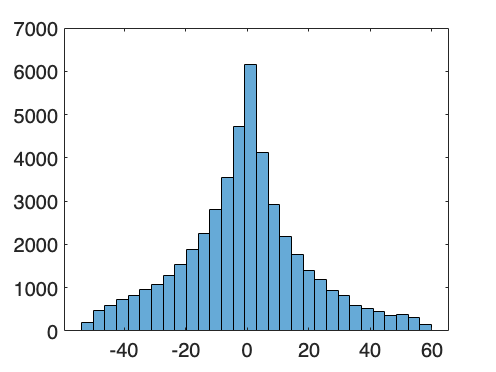

hist=histogram(filtered_data,30);

disp(min(filtered_data))

  -52.3789



disp(max(filtered_data))

   58.4691



[mu,sigma]=normfit(filtered_data);

**Laplace distribution estimation**

N= length(error_data);
u= sum(error_data)/N;
b= sum(abs(error_data-u))/N;
a=1/(2*b);

xx = mu-5*sigma:.1:mu+5*sigma;
yo = a*exp(-(abs(xx-u)/b));

**plot separately**

% figure
% yyaxis left
% hist=histogram(filtered_data,30)
% hist.FaceColor = "#A8EB12"
% hist.EdgeColor= [0 0.4470 0.7410] 
% xlim([mu-3*sigma,mu+3*sigma])
% xlabel('Relative Error (%)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
% ylabel('Number of Instances','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
% % a2=axes;  
% yyaxis right
% fp=fplot(@(x)normpdf(x,mu,sigma),[mu-3*sigma,mu+3*sigma]);
% xlim([mu-3*sigma,mu+3*sigma])
% fp.LineStyle = '-.';
% fp.LineWidth =2;
% fp.Color =[0.9290 0.6940 0.1250];
% %set(a2,'box','off','yaxislocation','right','color','none')  
% % set(gca,'xticklabel',[]);
% ylabel('Probability density','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
% set(gcf,'Position',[100 100 900 300]);
% set(gca,'FontSize',12,'FontName','Times New Roman')
% ax = gca;
% ax.YAxis(1).Exponent = 4;

disp(mu)

   -0.8137



disp(sigma)

   20.3588



% figure
% yyaxis left
% hist=histogram(filtered_data,30,'FaceColor','[0.3010 0.7450 0.9330]','EdgeColor','[0 0.4470 0.7410]');box off 
% xlim([mu-5*sigma,mu+5*sigma])
% xlabel('Error','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
% ylabel('Number of samples','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
% %a2=axes;  
% yyaxis right
% plot(xx,yo,'--','color',[0.8500 0.3250 0.0980],'linewidth',2);
% ylim([0 0.015])
% %set(a2,'box','off','yaxislocation','right','color','none')  
% %set(gca,'xticklabel',[]);
% ylabel('Probability density','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
% %title 'The Gaussian Estimation of Wind Prediction Error'  
% set(gcf,'Position',[100 100 400 500]);
% set(gca,'FontSize',12,'FontName','Times New Roman')
% ax = gca;
% ax.YAxis(1).Exponent = 4;

w_cap = 1000;
w_path = '../inter_data/wind_fore_summer.mat';
wind_min = load(w_path);
testname = './inter/wind_data_test.mat';
load(testname, 'z');
test_sample = (z./(w_cap/100 * wind_min.data')-1)*100;
trainname =  './inter/wind_data.mat';
load(trainname, 'z');
train_sample = (z./(w_cap/100 * wind_min.data')-1)*100;

sample_num = size(test_sample);
S = sample_num(2)

S = 472

test_new = reshape(test_sample, 24*S, 1);

sample_num = size(train_sample);
S = sample_num(2)

S = 706

train_new = reshape(train_sample, 24*S, 1);

[mu_test,sigma_test]=normfit(test_new)

mu_test = -0.9516

sigma_test = 20.5145

[mu_train,sigma_train]=normfit(train_new)

mu_train = -0.8069

sigma_train = 20.3147

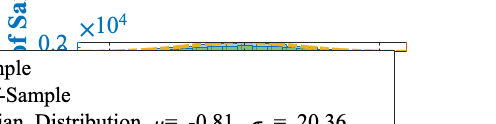

figure
yyaxis left
hist=histogram(train_new,30);
hist.FaceColor = [0.3010, 0.7450, 0.9330];
hist.EdgeColor= [0 0.4470 0.7410];
xlim([mu-3*sigma,mu+3*sigma])

hold on;
hist=histogram(test_new,30);
hist.FaceColor =[0.4660, 0.6740, 0.1880];
hist.EdgeColor= [0 0.4470 0.7410];
xlim([mu-3*sigma,mu+3*sigma])

xlabel('Relative Error (%)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
ylabel('Number of Samples','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

% legend('In-Sample', 'Out-of-Sample');
% a2=axes;  

yyaxis right

fp=fplot(@(x)normpdf(x,mu,sigma),[mu-3*sigma,mu+3*sigma]);
xlim([mu-3*sigma,mu+3*sigma])
fp.LineStyle = '-.';
fp.LineWidth =2;
fp.Color =[0.9290 0.6940 0.1250];
legend('In-Sample', 'Out-of-Sample','Gaussian Distribution \mu= -0.81, \sigma = 20.36');

legendFontSize = 10;
%set(a2,'box','off','yaxislocation','right','color','none')  
% set(gca,'xticklabel',[]);
ylabel('Probability density','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

set(gcf,'Position',[100 100 1200 300]);
set(gca,'FontSize',12,'FontName','Times New Roman')
ax = gca;
ax.YAxis(1).Exponent = 4;

% Save the entire figure, including all elements
figureFileName = './result/wind_sample.pdf'; % Specify the file name
saveas(gcf, figureFileName);